# Sprawozadanie

# z Laboratorium Metod numerycznych

## Ćwiczenie 5:

## Rozwiązywanie równań nieliniowych

Autor: Dominik Gajda, 240661

    Maksym Dmytruk, 240353

Data wykonania ćwiczenia: 23.11.2022

Data sporządzenia i oddania sprawozdania: 29.11.2022

Przedmiotem ćwiczenia jest rozwiązywanie równań postaci


$$f(x)=0$$


W trakcie zajęć zostaną zaimplementowane przynajmniej trzy metody: bisekcji, Newtona-Raphsona i siecznych.  

Na wstępie wczytano (pierwszą) funkcję testową

[fun1,ab,x0,x1,tv]=gen3INFcw5(240661,1)

fun1 = function_handle with value:
    @(x)x.*exp(x-2)-x.^2/2


ab =     1.8000    2.5000


x0 = 2.5000

x1 = 2.4000

tv = 2

Na wstępie, aby pewniono się, że funkcja testowa i przedział poszukiwań rozwiązania spełniają warunki stosowalności metody, sporządzono wykres

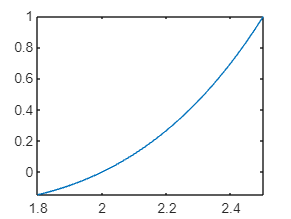

fplot(fun1,ab)

Funkcja przecina prostą `y=0,` zatem spełnia warunki stosowalności metody bisekcji.

### Metoda bisekcji

Napisano funkcję bisekcja o nagłówku

`function [c,chist]=bisekcja(fun, a, b, tol)`

która implementuje metodę bisekcji i oprócz przyybliżonej wartości rozwiązania równania, jako drugi argument wyjściowy zwraca historię obliczonych kolejno przybliżeń, czyli środków przedziałów, w których musi znajdować się rozwiązanie. Ograniczono do około 50 liczbę iteracji metody *(co prawda metoda bisekcji, jeśli zostanie poprawnie zaimplementowana, powinna zakończyć obliczenia bez tego ograniczenia, ale wymagałoby to w szczególności sprawdzania poprawności czwartego argumentu, określającego tolerancję obliczeń), *co ułatwi zarezerwowanie pamięci na przechowywanie historii obliczeń*.* Powinien też być sygnalizowany błąd, jeśli badana funkcja przyjmuje wartości tych samych znaków na końcach przedziału, w którym ma być poszukiwane rozwiązanie. 

fun=fun1

fun = function_handle with value:
    @(x)x.*exp(x-2)-x.^2/2


a=ab(1)

a = 1.8000

b=ab(2)

b = 2.5000

tol=1e-13

tol = 1.0000e-13

%=====================================================================
fa=fun(a);
fb=fun(b);
if fa*fb>0, error("BISEKCJA: Funkcja musi zmieniać znak w przedziale początkowym"); end

% Ustalenie maksymalnej liczby iteracji
N=50; 

% Rezerwacja pamięci na historię obliczeń
chist=nan(N,1);

% Pętla służąca ograniczeniu liczby iteracji
for k = 1:N
    c = 0.5 * (a + b);
    fc = fun(c);
    chist(k) = c;
    if fc == 0, break; end
    if fc * fa > 0
        a = c;
        fa = fc;
    elseif fc * fb > 0
        b = c;
        fb = fc;
    else, error("Błąd działania funkcji");
    end
    
    % Przedwczesne opuszczenie pętli, jeśli spełnione jest kryterium zakończenia obliczeń
    if abs(b-a) < tol, break; end
    
end
if k==N, warning("BISEKCJA: Przekroczono maksymalną liczbę iteracji"); end
% "Skrócenie" wektora z historią obliczeń    
chist=chist(1:k);
%=====================================================================
c-tv

ans = 3.4195e-14

Obliczony błąd jest mniejszy od tolerancji, zatem funkcja została zaimplementowana prawidłowo.

Po sprawdzeniu poprawności działania kodu w formie skryptu, skopiowano go do kolejnej sekcji i przetworzono przy pomocy opcji menu kontekstowego na funkcję lokalną.

Po skorygowaniu nazwy i list parametrów funkcji testowo wywołano funkcję. 

fun=fun1

fun = function_handle with value:
    @(x)x.*exp(x-2)-x.^2/2


a=ab(1)

a = 1.8000

b=ab(2)

b = 2.5000

tol=1e-13

tol = 1.0000e-13

%=====================================================================
[c, chist] = bisekcja(fun, a, b, tol);
%=====================================================================
c-tv

ans = 3.4195e-14

Sporządzono wykres wartości bezwzględnej kolejnych przybliżeń w funkcji numeru iteracji

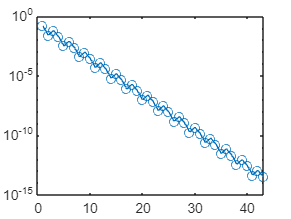

% Wykres historii kolejnych przybliżeń
[~,chist]=bisekcja(fun, a, b, tol);
semilogy(abs(chist-tv),'o-')

xlabel('numer iteracji')
ylabel('moduł błędu przybliżenia')

### Metoda *regula falsi* (nadprogramowe)

Zmodyfikowano napisaną funkcję tak, aby wykorzystywała nie tylko informację o znaku wartości funkcji, ale także ich wartości bezwzględnej. Dokładniej stworzono implementację metody regula falsi, którz przy tych samych założeniach, co metoda bisekcji, dotyczących znaku funkcji, za kolejne przybliżenie przyjmuje nie środek przedziału, tylko przecięcie odcinka przechodzącego przez punkty $(a, f(a))$ i $(b, f(b)$ z osią odciętych (czyli $c=\frac{(a\cdot f(b)-b\cdot f(a))}{(f(b)-f(a))}$)

Metoda bisekcji jest w pewnym stopniu rozrzutna, ponieważ wykorzystuje tylko znak funkcji, a nie jak duża jest różnica między wartością funkcji w środku przedziału, a wartościami funkcji na krańcach predziałów. Punkt **c** jest więc obliczany w punkcie przecięcia prostej łączącej punkty funkcji na krańcach przeziałów z prostą `y=0`. 

fun=fun1

fun = function_handle with value:
    @(x)x.*exp(x-2)-x.^2/2


a=ab(1)

a = 1.8000

b=ab(2)

b = 2.5000

tol=1e-13

tol = 1.0000e-13

%=====================================================================
fa=fun(a);
fb=fun(b);
if fa*fb>0, error("BISEKCJA: Funkcja musi zmieniać znak w przedziale początkowym"); end

% Ustalenie maksymalnej liczby iteracji
N=50; 

% Rezerwacja pamięci na historię obliczeń
chist=nan(N,1);

% Pętla służąca ograniczeniu liczby iteracji
for k = 1:N
    c = (a * fb - b * fa) / (fb - fa);
    fc = fun(c);
    chist(k) = c;
    if fc == 0, break; end
    if fc * fa > 0
        a = c;
        fa = fc;
    elseif fc * fb > 0
        b = c;
        fb = fc;
    else, error("Błąd działania funkcji");
    end
    
    % Przedwczesne opuszczenie pętli, jeśli spełnione jest kryterium zakończenia obliczeń
    if abs(b-a) < tol, break; end
    
end
if k==N, warning("BISEKCJA: Przekroczono maksymalną liczbę iteracji"); end

% "Skrócenie" wektora z historią obliczeń    
chist=chist(1:k);
%=====================================================================

fun=fun1

fun = function_handle with value:
    @(x)x.*exp(x-2)-x.^2/2


a=ab(1)

a = 1.8000

b=ab(2)

b = 2.5000

tol=1e-13

tol = 1.0000e-13

%=====================================================================
[c, chist] = regulafalsi(fun, a, b, tol)

c = 2.0000

chist =     1.8896
    1.9418
    1.9701
    1.9849
    1.9924
    1.9962
    1.9981
    1.9991
    1.9995
    1.9998


%=====================================================================
format long
c-tv

ans =     -2.220446049250313e-16


Sporządzono wykres wartości bezwzględnej kolejnych przybliżeń w funkcji numeru iteracji

% Wykres historii kolejnych przybliżeń
[~,chist]=regulafalsi(fun, a, b, tol);

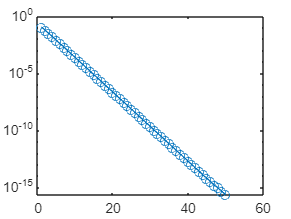

semilogy(abs(chist-tv),'o-')

xlabel('numer iteracji')
ylabel('moduł błędu przybliżenia')

### Metoda Newtona-Raphsona I rzędu

Metoda Newtona wymaga podania kodu obliczającego pochodną funkcji, której miejsce zerowe chcemy znaleźć, więc została udostępniona funkcja pomocnicza `derivative`, która zwraca uchwyt do takiej funkcji anonimowej. Warto przestudiować kod tej funkcji. Ma ona liczne ograniczenia, ale została udostępniona ze względu na fakt, że użycie komendy `syms` wywołuje komunikaty o błędach analizatora kodu w Live Script Editor.


$$x_{k+1} = x_k -\frac{f(x_k)}{f'(x_{k})}$$


Funkcja implementująca metodę Newtona-Raphsona I rzędu powinna mieć nagłówek

`function [c, xhist]=newton(fun, dfun, x0, tol)`

fun=fun1

fun = function_handle with value:
    @(x)x.*exp(x-2)-x.^2/2


dfun=derivative(fun) % Obliczenie pochodnej przy pomocy funkcji pomocniczej

dfun = function_handle with value:
    @(x)-x+exp(x-2.0)+x.*exp(x-2.0)


%=============================================================================
% Ustalenie maksymalnej liczby iteracji
N=50; 

x=x0;
fx=fun(x);

% Rezerwacja pamięci na historię obliczeń
xhist=nan(N,1);

% Pętla służąca ograniczeniu liczby iteracji
xhist(1)=x0;
for k=2:N
    xnew = x - fx / dfun(x);
    xhist(k) = xnew;
    fxnew = fun(xnew);
    
    % Przedwczesne opuszczenie pętli, jeśli spełnione jest kryterium zakończenia obliczeń
    if xnew == 0, break; end
    if abs(xnew - x) < tol, break; end 
    
    x = xnew;
    fx = fxnew;
end
if k == N, warning("NEWTON: Przekroczono maksymalną liczbę iteracji"); end

% "Skrócenie" wektora z historią obliczeń    
xhist=xhist(1:k); 
%=============================================================================

Po sprawdzeniu poprawności działania kodu w formie skryptu, skopiowano go do kolejnej sekcji i przetworzono przy pomocy opcji menu kontekstowego na funkcję lokalną. 

fun=fun1

fun = function_handle with value:
    @(x)x.*exp(x-2)-x.^2/2


dfun=derivative(fun) % Obliczenie pochodnej przy pomocy funkcji pomocniczej

dfun = function_handle with value:
    @(x)-x+exp(x-2.0)+x.*exp(x-2.0)


%=============================================================================
[x, xhist] = newton(fun, dfun, x0, tol)

x =      2


xhist =    2.500000000000000
   2.195216105928398
   2.041876867755830
   2.002438075054336
   2.000008875446489
   2.000000000118158
   2.000000000000000
   2.000000000000000


%=============================================================================
format long
x - tv

ans =      0


Wynik co do wartości jest równy zero, zostało zatem znalezione dokładne rozwiązanie funkcji.

Sporządzono wykres modułu błędu kolejnych przybliżeń metody Newtona dla pierwszej funkcji testowej

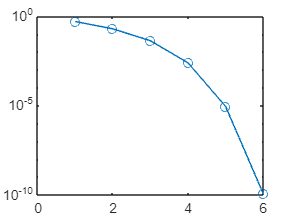

[x, xhist]=newton(fun, dfun, x0, tol);
semilogy(abs(xhist-tv),'o-')

xlabel('numer iteracji')
ylabel('moduł błędu przybliżenia')

### Uwagi

Wadą metody Newtona-Raphsona jest to, że jest zbieżna wyłącznie lokalnie, potrzeba za tym dobrego przybliżenia początkowego. Dodatkową wadą jest konieczność dysponowania wzorem na pochodną funkcji. 

### Metoda siecznych

Następnie napisano funkcję implementującą metodę siecznych, w której wartość pochodnej ze wzoru metody Newtona przybliżona jest ilorazem różnicowym na podstawie dwóch ostatnich przybliżeń (tym samym musimy podać dwa **różne** punkty startowe)


$$x_{k+1} = x_k - f(x_k)\frac{x_k-x_{k-1}}{f(x_k)-f(x_{k-1})}$$


Funkcja powinna mieć nagłówek:

`function [x, xhist]=sieczne(fun, x0, x1, tol)`

fun=fun1

fun = function_handle with value:
    @(x)x.*exp(x-2)-x.^2/2


tol=1e-13

tol =      1.000000000000000e-13


%=====================================================================
% Sprawdzenie poprawności danych wejściowych

% Ustalenie maksymalnej liczby iteracji
N=50; 

% Rezerwacja pamięci na historię obliczeń
xhist=nan(N,1);

xkm1 = x0;
xk = x1;
fxkm1 = fun(xkm1);
fxk = fun(xk);

% Pętla służąca ograniczeniu liczby iteracji
xhist(1)=x0;
xhist(2)=x1;
for k=3:N
    xnew = xk - fxk * (xk - xkm1) / (fxk - fxkm1);
    fxnew = fun(xnew);
    xhist(k) = xnew;
    
    % Przedwczesne opuszczenie pętli, jeśli spełnione jest kryterium zakończenia obliczeń
    if fxnew == 0, x = xnew; break; end
    if abs(xhist(k)-xhist(k-1))<tol, break; end

    xkm1 = xk;
    fxkm1 = fxk;
    xk = xnew;
    fxk = fxnew;
    x = xnew;
end
if k==N, warning("SIECZNE: Przekroczono maksymalną liczbę iteracji"); end

% "Skrócenie" wektora z historią obliczeń    
xhist=xhist(1:k); 

%=====================================================================

fun=fun1

fun = function_handle with value:
    @(x)2*exp(x-1)-x-1


tol=1e-13

tol =      1.000000000000000e-13


%=====================================================================
[xs, xhist] = sieczne(fun, x0, x1, tol);
%=====================================================================
disp(x-tv)

     0



disp(length(xhist))

     8



Wynikiem operacji jest zero, zatem znaleźliśmy dokładnie rozwiązanie równania.

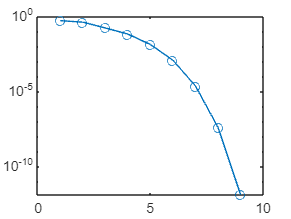

[xs, xhists]=sieczne(fun, x0, x1, tol);
semilogy(abs(xhists-tv),'o-')

Sprawdzenie czy wzór 


$$x_{k+1} =\frac{f(x_k)x_{k-1}-f(x_{k-1})x_k}{f(x_k)-f(x_{k-1})}$$


który jest algebraicznie równoważny z zastosowanym wcześniej wzorem na kolejne przybliżenie metody siecznych, prowadzi do tych samych wyników. W celu sprawdzenia trzeba stworzyć kopię funkcji sieczne, nazwać sieczne2 i zmienić (tylko) wzór obliczający kolejne przybliżenie.

fun=fun1

fun = function_handle with value:
    @(x)2*exp(x-1)-x-1


tol=1e-13

tol =      1.000000000000000e-13


%=====================================================================
% Ustalenie maksymalnej liczby iteracji
N=50; 

% Rezerwacja pamięci na historię obliczeń
xhist=nan(N,1);

xkm1 = x0;
xk = x1;
fxkm1 = fun(xkm1);
fxk = fun(xk);

% Pętla służąca ograniczeniu liczby iteracji
xhist(1)=x0;
xhist(2)=x1;
for k=3:N
    xnew = (fxk * xkm1 - fxkm1 * xk) / (fxk - fxkm1);
    fxnew = fun(xnew);
    xhist(k) = xnew;
    
    % Przedwczesne opuszczenie pętli, jeśli spełnione jest kryterium zakończenia obliczeń
    if fxnew == 0, x = xnew; break; end
    if abs(xhist(k)-xhist(k-1))<tol, break; end

    xkm1 = xk;
    fxkm1 = fxk;
    xk = xnew;
    fxk = fxnew;
    x = xnew;
end
if k==N, warning("SIECZNE: Przekroczono maksymalną liczbę iteracji"); end

% "Skrócenie" wektora z historią obliczeń    
xhist=xhist(1:k); 
%=====================================================================
disp(x-tv)

     0



disp(k)

     8



Powyższy wzór daje zbieżne wyniki co metoda siecznych. Rozwiązanie równania zostało znalezione dla k=8, a zatem po 6 iteracjach pętli, tak samo jak w przypadku metody siecznych.

Wykonano wykresy dla wszystkich zaimplementowanych metod, celem porównania szybkości ich zbieżności

% Aby uniknąć błędów, wczytać ponownie funkcję testową i przygotować
% zmienne pomocnicze
[fun1,ab,x0,x1,tv]=gen3INFcw5(654321,1)

fun1 = function_handle with value:
    @(x)2*exp(x-1)-x-1


ab =    0.900000000000000   1.200000000000000


x0 =    1.200000000000000


x1 =    1.100000000000000


tv =      1


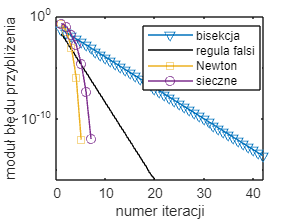

fun=fun1;
dfun=derivative(fun1);
a=ab(1);b=ab(2);

[~, chist1] = bisekcja(fun, a, b, tol);
[~, chistf1] = regulafalsi(fun, a, b, tol);
[~, xhist1] = newton(fun, dfun, x0, tol);
[~, xhists1]= sieczne(fun, x0, x1, tol);

semilogy(1:length(chist1),abs(chist1-tv),'v-', ...
         1:length(chistf1),abs(chistf1-tv),'k-', ...
         1:length(xhist1),abs(xhist1-tv),'s-', ...
         1:length(xhists1),abs(xhists1-tv),'o-')
xlabel('numer iteracji')
ylabel('moduł błędu przybliżenia')
legend('bisekcja','regula falsi','Newton','sieczne','Location','best')

### Uwagi

Z wykresu można odczytać, że najszybciej do rozwiązania zbiega metoda Newtona oraz metoda siecznych. 

Metoda Regula falsi jest wyraźnie szybsza od metody bisekcji, lecz wciąż zbieżna liniowo.

### Działanie badanych metod dla funkcji mających pierwiastki wielokrotne

Powtórzono badanie wszystkich zaimplementowanych metod posługując się drugą funkcją testową, której pierwiastek jest wielokrotny. Wczytano w tym celu drugą funkcję testową i przeanalizowano jej wykres.

[fun2,ab2,x02,x12,tv2]=gen3INFcw5(240661,2) 

fun2 = function_handle with value:
    @(x)cos(pi*x)-pi*(x+1/2)


ab2 =   -0.600000000000000  -0.300000000000000


x02 =   -0.300000000000000


x12 =   -0.350000000000000


tv2 =   -0.500000000000000


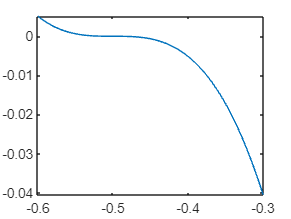

fplot(fun2,ab2)

Funkcja na dużym zakresie przyjmuje wartość zero. Sytuacja, która wiąże się ze złym uwarunkowaniem zadania rozwiązania równania nieliniowego.

fun=fun2

fun = function_handle with value:
    @(x)cos(pi*x)-pi*(x+1/2)


a=ab2(1),b=ab2(2)

a =   -0.600000000000000


b =   -0.300000000000000


tol=1e-16

tol =      1.000000000000000e-16


dfun=derivative(fun)

dfun = function_handle with value:
    @(x)-pi-pi.*sin(x.*pi)



[~,chist2]=bisekcja(fun, a, b, tol);

[~,chistr2]=regulafalsi(fun, a, b, tol);

[~, xhist2]=newton(fun, dfun, x02, tol);

[~, xhists2]=sieczne(fun, x02, x12, tol);

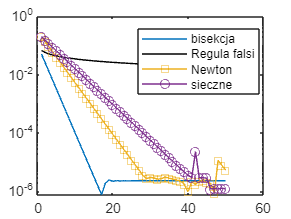


semilogy(1:length(chist2),abs(chist2-tv2),1:length(chistr2),abs(chistr2-tv2),'k-',1:length(xhist2),abs(xhist2-tv2),'s-',1:length(xhists2),abs(xhists2-tv2),'o-')
legend('bisekcja','Regula falsi','Newton','sieczne','Location','best')

xlabel('numer iteracji')
ylabel('moduł błędu przybliżenia')

### Uwagi

Przebieg wykresu w przypadku pierwiastka wielokrotnego zmienił się diamtralnie. Najszybsza okazała się metoda bisekcji, następnie metoda Newtona, a najwolniej zbiegała metoda siecznych. Metoda siecznych i Newtona wykazują zbieżność liniową.

W przypadku bardziej skomplikowanych funkcji moglibyśmy się spodziewać, że w wyniku błędów zaokrągleń kolejne przybliżenia mogą okazać się gorsze niż poprzednie.

Metoda Regula falsi nie wykazuje zbieżności, co świadczy o jej braku zastosowania w przypadku źle uwarunkowanych zadań.

### Rozwiązywanie układów równań nieliniowych

Na przykładzie bardzo prostego układu dwóch równań z dwiema niewiadomymi, zaimplementowano metodę Newtona

Dla funkcji dwóch zmiennych także została napisana funkcja pomocnicza` jacob`, wyznaczająca jakobian (nazwa wynika z faktu, że funkcja `jacobian` jest częścią Symbolic Math Toolbox (jest ona zresztą wykorzystywana w funkcji `jacob`)

[funxy,xy0,xytrue] = gen3INFcw5(240661,4) 

funxy = function_handle with value:
    @(x,y)[2*x.*y-x+2*y+3;x.^2+4*y.^2+2*x-4*y-15]


xy0 =    3.300000000000000
  -0.300000000000000


xytrue =      3
     0


funxy(xytrue(1),xytrue(2)) % Sprawdzenie poprawności danych przykładowych

ans =      0
     0



Jac = jacob(funxy) % Obliczenie Jacobianu

Jac = function_handle with value:
    @(x,y)reshape([y.*2.0-1.0,x.*2.0+2.0,x.*2.0+2.0,y.*8.0-4.0],[2,2])


Zaimplementowano metodę Newtona w formie skryptu bez przekształcania w funkcję

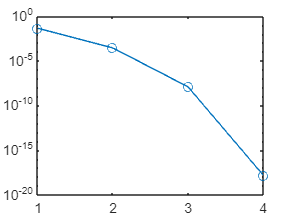

xy = xy0;
er = zeros(1,10);
for k = 1:10
    xynew = xy - Jac(xy(1), xy(2)) \ funxy(xy(1), xy(2));
    if norm(xynew-xy) < tol, break; end
    er(k) = norm(xynew-xytrue);
    xy = xynew;
end
er = er(1:k);
semilogy(er,'o-')

xlabel('numer iteracji')
ylabel('moduł błędu przybliżenia metody Newtona')

### Obserwacje uwagi i wnioski

Metoda Newtona owszem działa i wykazuje zbieżność dla niewielkiej liczby iteracji, lecz jest zbieżna lokalnie. Jeżeli nie mamy dostatecznie dobrego przybliżenia to nie mamy gwarancji, że działa. Ponadto obliczenie Jakobianu jest trudniejsze niż obliczenie pochodnej.

Implementacja Jakobianu jest wykonalna, ale nie jest prosta na tyle, by operacja ta mogła stać się funkcją biblioteczną.

function [c, chist] = bisekcja(fun, a, b, tol)
% Sprawdzenie poprawności danych wejściowych
fa=fun(a);
fb=fun(b);
if fa*fb>0, error("BISEKCJA: Funkcja musi zmieniać znak w przedziale początkowym"); end

% Ustalenie maksymalnej liczby iteracji
N=50; 

% Rezerwacja pamięci na historię obliczeń
chist=nan(N,1);

% Pętla służąca ograniczeniu liczby iteracji
for k = 1:N
    c = 0.5 * (a + b);
    fc = fun(c);
    chist(k) = c;
    if fc == 0, break; end
    if fc * fa > 0
        a = c;
        fa = fc;
    elseif fc * fb > 0
        b = c;
        fb = fc;
    else, error("Błąd działania funkcji");
    end
    
    % Przedwczesne opuszczenie pętli, jeśli spełnione jest kryterium zakończenia obliczeń
    if abs(b-a) < tol, break; end
    
end
if k==N, warning("BISEKCJA: Przekroczono maksymalną liczbę iteracji"); end
% "Skrócenie" wektora z historią obliczeń    
chist = chist(1:k);
end

% ==================================================


function [x, xhist] = newton(fun, dfun, x0, tol)
% Ustalenie maksymalnej liczby iteracji
N=50; 

x=x0;
fx=fun(x);

% Rezerwacja pamięci na historię obliczeń
xhist=nan(N,1);

% Pętla służąca ograniczeniu liczby iteracji
xhist(1)=x0;
for k=2:N
    xnew = x - fx / dfun(x);
    xhist(k) = xnew;
    fxnew = fun(xnew);
    
    % Przedwczesne opuszczenie pętli, jeśli spełnione jest kryterium zakończenia obliczeń
    if xnew == 0, break; end
    if abs(xnew - x) < tol, break; end 
    
    x = xnew;
    fx = fxnew;
end
if k == N, warning("NEWTON: Przekroczono maksymalną liczbę iteracji"); end

% "Skrócenie" wektora z historią obliczeń    
xhist = xhist(1:k); 
end

% ==================================================


function [x, xhist] = sieczne(fun, x0, x1, tol)
% Ustalenie maksymalnej liczby iteracji
N=50; 

% Rezerwacja pamięci na historię obliczeń
xhist=nan(N,1);

xkm1 = x0;
xk = x1;
fxkm1 = fun(xkm1);
fxk = fun(xk);

% Pętla służąca ograniczeniu liczby iteracji
xhist(1)=x0;
xhist(2)=x1;
for k=3:N
    xnew = xk - fxk * (xk - xkm1) / (fxk - fxkm1);
    fxnew = fun(xnew);
    xhist(k) = xnew;
    
    % Przedwczesne opuszczenie pętli, jeśli spełnione jest kryterium zakończenia obliczeń
    if fxnew == 0, x = xnew; break; end
    if abs(xhist(k)-xhist(k-1))<tol, break; end
    
    xkm1 = xk;
    fxkm1 = fxk;
    xk = xnew;
    fxk = fxnew;
    x = xnew;
end
if k==N, warning("SIECZNE: Przekroczono maksymalną liczbę iteracji"); end

% "Skrócenie" wektora z historią obliczeń    
xhist = xhist(1:k); 
end


% ==================================================


function [c, chist] = regulafalsi(fun, a, b, tol)
fa=fun(a);
fb=fun(b);
if fa*fb>0, error("REGULAFALSI: Funkcja musi zmieniać znak w przedziale początkowym"); end

% Ustalenie maksymalnej liczby iteracji
N=50; 

% Rezerwacja pamięci na historię obliczeń
chist=nan(N,1);

% Pętla służąca ograniczeniu liczby iteracji
for k = 1:N
    c = (a * fb - b * fa) / (fb - fa);
    fc = fun(c);
    chist(k) = c;
    if fc == 0, break; end
    if fc * fa > 0
        a = c;
        fa = fc;
    elseif fc * fb > 0
        b = c;
        fb = fc;
    else, error("REGULAFALSI: Błąd działania funkcji");
    end
    
    % Przedwczesne opuszczenie pętli, jeśli spełnione jest kryterium zakończenia obliczeń
    if abs(b-a) < tol, break; end
    
end
if k==N, warning("REGULAFALSI: Przekroczono maksymalną liczbę iteracji"); end
% "Skrócenie" wektora z historią obliczeń    
chist = chist(1:k);
end